%clear 
%clc

Making signal

% samping frequency
fs = 4000;
% time duration
tmax = 1-1/fs;
% time vector
t = 0:1/fs:tmax;
s = length(t);
% frequency vector
f = linspace(0,fs-fs/s,s);
% centra lfrequency of sine waves
w = [200,400,700,850];
% hann window 200 samples
mask = hann(200);
% time delay of the signals
inds = [1400,1000,1200,800];
% allocare memory for y
y = zeros(length(t),1);
% add sine waves
for i = 1:length(w)
 m = zeros(s,1);
 m(inds(i):inds(i)+length(mask)-1) = mask;
 y_temp = sin(2*pi*t*w(i)).*m.';
 y = y+y_temp.';
end

2.1

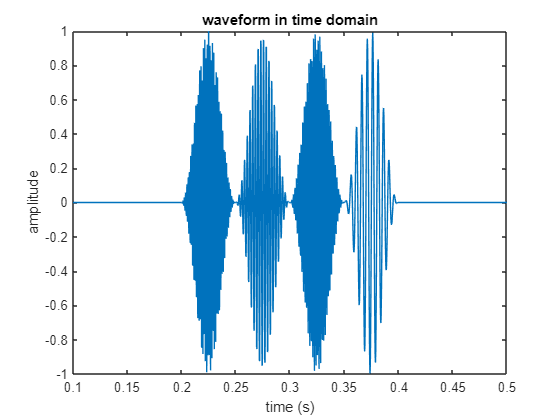

%plotting initial waveform
figure()
plot(t,y)
title('waveform in time domain')
xlabel('time (s)')
ylabel('amplitude')
xlim([0.1,0.5])

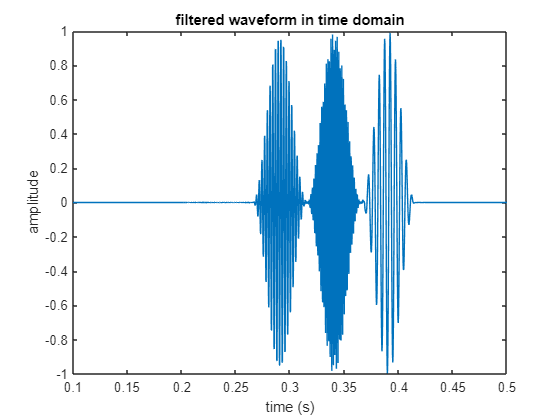

%filtering the signal using designed FIR filter
yf=filter(Hd,y);
%plotting filtered waveform
figure()
plot(t,yf)
title('filtered waveform in time domain')
xlabel('time (s)')
ylabel('amplitude')
xlim([0.1,0.5])

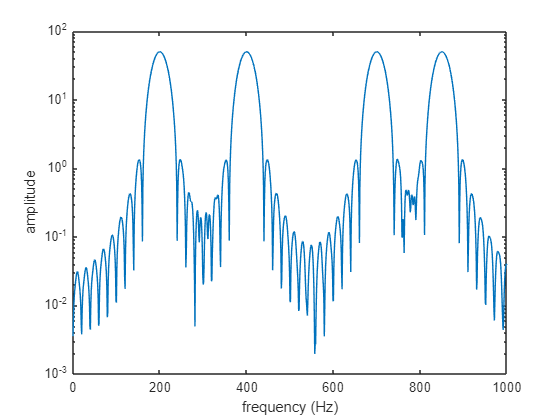

%preparing frequency spectrum
N=length(yf);
df=fs/N;
fv=(0:N-1)*df;
%plotting frequency spectrum
Y=fft(y);
Y2=fft(yf);
%plotting FS of initial waveform
figure()
semilogy(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,1000])

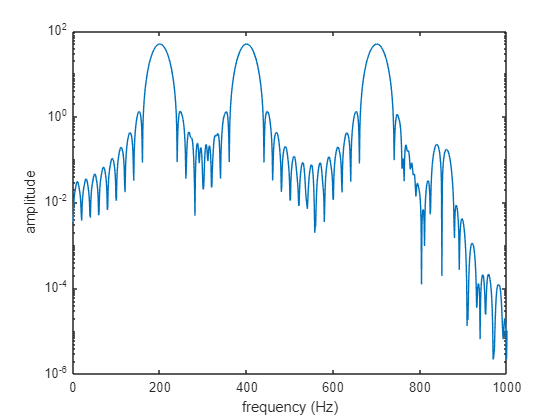

%plotting FS of filtered waveform
figure()
semilogy(fv , abs(Y2))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,1000])

2.2

%plotting initial waveform
figure()
plot(t,y)
title('waveform in time domain')
xlabel('time (s)')
ylabel('amplitude')
xlim([0.1,0.5])

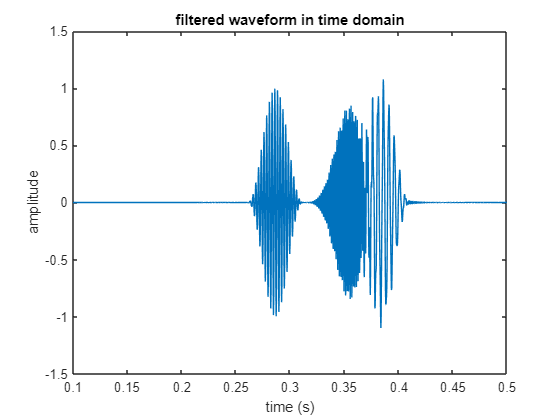

%filtering the signal using designed IIR filter
yf=filter(HdIIR,y);
%plotting filtered waveform
figure()
plot(t,yf)
title('filtered waveform in time domain')
xlabel('time (s)')
ylabel('amplitude')
xlim([0.1,0.5])

%preparing frequency spectrum
N=length(yf);
df=fs/N;
fv=(0:N-1)*df;
%plotting FS
Y=fft(y);
Y2=fft(yf);
%initial FS
figure()
semilogy(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,1000])

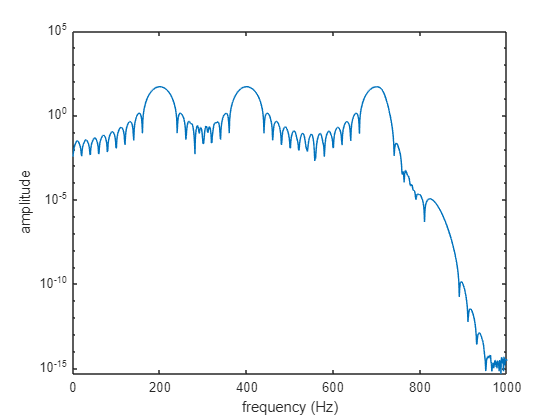

%IIR filtered FS
figure()
semilogy(fv , abs(Y2))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,1000])

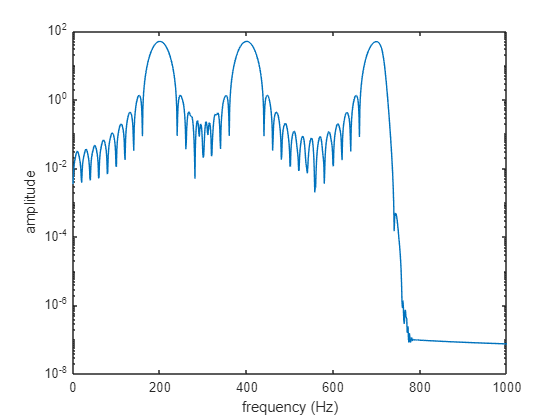

%applying zero-phase filtration
yfilt=filtfilt(HdIIR.sosMatrix,HdIIR.ScaleValues,y);
%plotting FS using zero-phase filtration
Yfilt=fft(yfilt);
figure()
semilogy(fv , abs(Yfilt))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,1000])

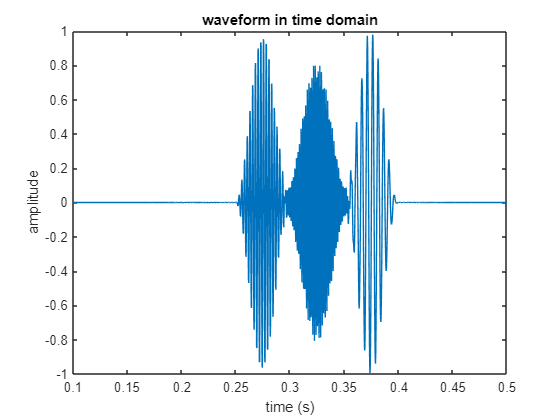

%plotting zero-phased filtered signal
figure()
plot(t,yfilt)
title('waveform in time domain')
xlabel('time (s)')
ylabel('amplitude')
xlim([0.1,0.5])